# Add Wind data and NNT to BS data. 

## Load data

Load Original file (without wind)

BS = readtable('BS/SEM2018_allEchoes_cleaned.csv','TreatAsEmpty','NA');

Remove data from the 2nd of January

BS(BS.time_string>datetime('2019-01-01 12:00'),:)=[];

Convert predicted_class ("insect" or bird) into a boolean

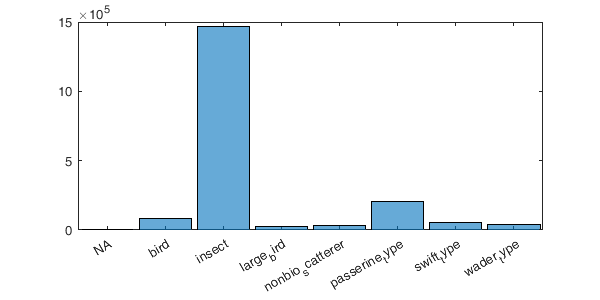

figure('position',[0 0 600 300]); histogram(categorical(BS.class))

BS(strcmp(BS.class,'NA'),:)=[];
BS(strcmp(BS.class,'nonbio_scatterer'),:)=[];
BS(strcmp(BS.class,'swift_type'),:)=[]; % Remvoe because many swift at sempach not representative
BS.isBird = true(height(BS),1);
BS.isBird(strcmp(BS.class,'insect'))=false;

Remode day-time data (checked with sunsetsunrise.mat and same result). 

BS(BS.is_night==0,:)=[];

Save as complex matrix

BS.groundspeed = BS.speed .* exp( mod(-deg2rad(BS.direction)+90,360)*1i);

Delete unused variables

BS = removevars(BS,{'echoID','time_stamp','stc_level','pegel','pol_ratio','p_class','p_nonbio','version_RFC_class',...
    'wff','wff_cred','version_RFC_wff','refRCS_diam','mtrf',...
    'protocolID','siteID','startTime','stopTime','rotate','stc','threshold','autoThreshold',...
    'time_since_protocol_begin','time_stamp_ltz',...
    'is_night','date_sunset','daynight_start','daynight_stop','duration_day_night_h','duration_day_night_sec'...
    'direction_c','alpha_c','theta_c','speed','direction'});

Sort table based on date

BS = sortrows(BS,'time_string');

**Add wind data**

Combine COSMO File (~1min)

Define grid size and variables

c.level = 50:50:3000;
c.time = datetime('2018-01-01 00:00'):1/24:datetime('2018-12-31 23:00');
id_day = datenum(dateshift(c.time,'start','day')-c.time(1))+1;
c_DD = nan(numel(c.time),numel(c.level));
c_FF = c_DD;
t= c_DD;
t2=NaT(numel(c.time),numel(c.level));

Read all file and combine into matrices

tmp=dir('cosmo\');
files = {tmp.name};
files = files(contains(files,'cosmo1'));
for i_f=1:numel(files)
    T = readtable(['cosmo\' files{i_f}],'HeaderLines',17);
    c_FF(id_day==i_f,:)=reshape(T(strcmp(T.PARAMETER,'FF'),:).P_SPA,24,numel(c.level));
    c_DD(id_day==i_f,:)=reshape(T(strcmp(T.PARAMETER,'DD'),:).P_SPA,24,numel(c.level));
    t(id_day==i_f,:)=reshape(T(strcmp(T.PARAMETER,'DD'),:).LEVEL,24,numel(c.level));
    t2(id_day==i_f,:)=reshape(T(strcmp(T.PARAMETER,'DD'),:).DATE_TIME,24,numel(c.level));
end

Save as complex matrix

c.W = c_FF .* exp( mod(-deg2rad(c_DD)+90,360)*1i);

Interpolate wind at BS measurement

F = griddedInterpolant({datenum(c.time),c.level},c.W);
BS.windspeed = -F(datenum(BS.time_string),BS.height); % COSMO provide direction of origine of wind.

Figure

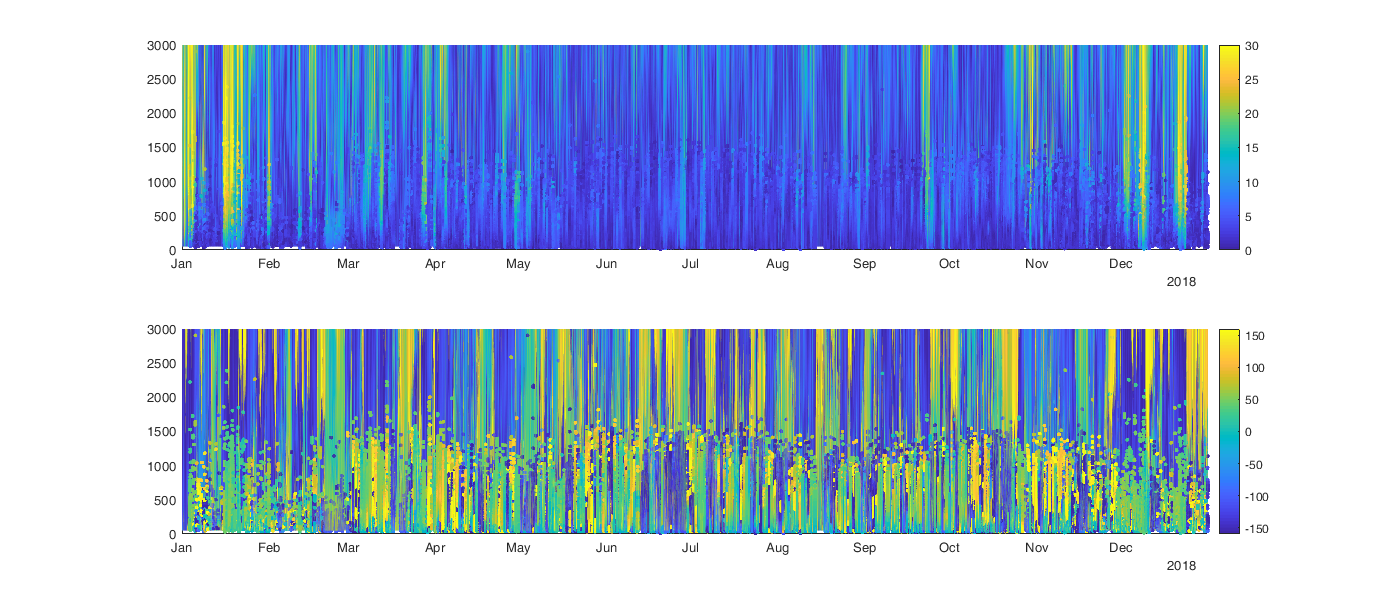

figure('position',[0 0 1400 600]); hold on;
subplot(2,1,1); hold on
surf(c.time',c.level',abs(c.W)');
shading interp;
scatter(BS.time_string,BS.height,[],abs(BS.windspeed),'.')
colorbar; caxis([0 30]); xlim([c.time(1) c.time(end)])

subplot(2,1,2); hold on;
surf(c.time',c.level',rad2deg(angle(c.W))'); shading interp;
scatter(BS.time_string,BS.height,[],rad2deg(angle(BS.windspeed)),'.')
colorbar;caxis([-160 160]); xlim([c.time(1) c.time(end)])

Write data

save('BS/Sempach_2018_cleaned','BS');